# Modsim Project 3

*Olivia Chang and Meredith Alley*

## Question

If a penny launcher throws several pennies simulatenously at a piano from a fixed distance, at what angle and speed does each penny need to be thrown in order to play a song on the piano? i.e. such that each penny lands at a different time, in sync with the song?

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Increase understanding of optimization

- Increase understanding of physics

- Increase flexibility of code

- Use GitHub effectively

## Methodology, Part 1: The Model

### Schematic Diagram

note: should add in axes?

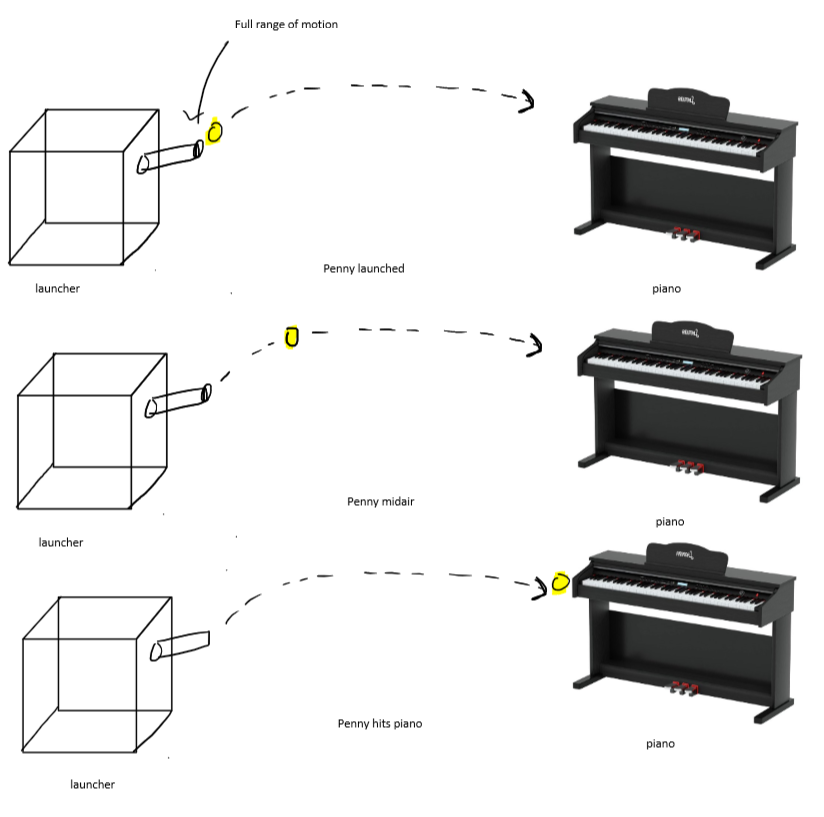

The penny launcher has multiple slots through which pennies are launched corresponding to each key (and thus note); each calibrated such that the z position of the slot is aligned with the desired key. The launcher is able to shoot multiple pennies simulatenously from the same slot at an infinitely high speed.

### Free Body Diagram

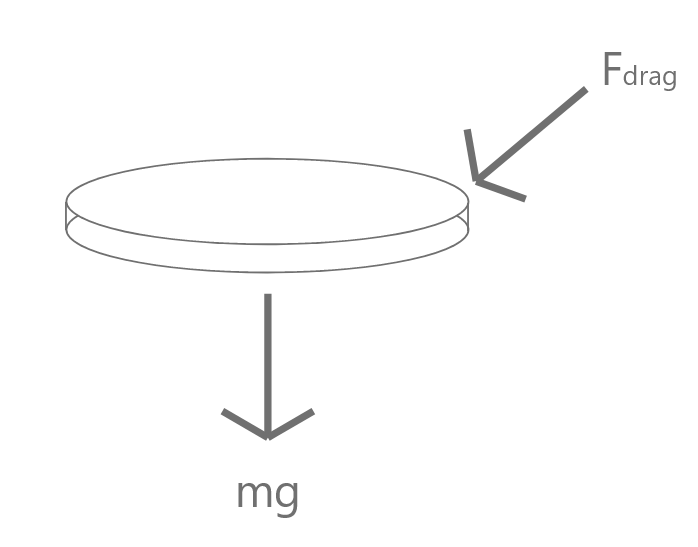

The forces affecting the penny are drag and gravity; in the y direction, the components affecting the penny are the vertical force of drag, or $\frac{Fd_y }{m}$, and gravity $F_g$

### Mathematical Model

**Parameters**

- **Penny weight:** 2.5g

- **Penny area affected by drag:** $2\ldotp 9{*10}^{-5}$$m^2$

- **Penny density: **$7\ldotp 185{*10}^{-6} m^3$

- **X distance to piano: **1 meter. This is a rather arbitrarily chosen value, but it is also simple and additionally a realistic value for an actual penny launcher.

- **Y distance from penny launcher and piano: **for simplicity of the model, we have set up the model such that the penny launcher and piano are the same height.

**2nd Order ODEs**


$$\frac{d^2 y}{dt^2 }=\frac{Fd_y }{m}-F_g$$



$$\frac{d^2 x}{dt^2 }=\frac{Fd_x }{m}$$


**1st Order ODEs**

**[FILL IN]**

### Assumptions

- The penny will always be travelling in the direction of a side, so that the face of the penny is never involved in the drag equations.

- The penny can reach impossibly high speeds: the terminal velocity of a penny is between 13.4112 m/s and 22.352 m/s. In order for the penny to land after, say, 25 seconds, and still be shot from a short distance, the penny has to be shot at speeds much greater than 22 m/s. Therefore, to make the question possible, we have assumed terminal velocity does not apply in this scenario.

- Each angle has a corresponding speed for which the penny *will* hit the piano (i.e. reach the x and y position of the piano at the same time) if launched at that angle and speed. 

- With the force of drag, there will not necessarily be an angle/speed combo that makes the penny hit the piano at the *exact* given time, but there will be one close enough that the difference is effectively nothing to the listener.

- The pennies magically disappear after hitting the keyboard. They do not bounce off the keyboard and interfere with the trajectory of the other pennies.

- The penny will hit the piano keys hard enough to actually play a note, however, even though some will hit the piano at impossibly high speeds, these piano keys are impossibly strong and will not break.

**Global Variables/Conversions**

global initial_height_launcher x_distance_to_piano y_distance_to_piano;
initial_height_launcher = 1;
x_distance_to_piano = 1;
y_distance_to_piano = 0;

## Methodology, Part 2: Code Setup and Verification

#### ODE45 Simulation

First, we set up a simulator function called `ode_penny` that accepts a speed and angle, simulates the penny's trajectory when launched at that speed and angle. The simulation stops when the penny reaches the y position of the piano, and returns four variables: `T`, a matrix of the time steps, `M`, a matrix containing the x and y position of the penny at each time step, `did_hit_piano`, a boolean that is true if the penny hit the piano, and `end_time`, the time it took for the penny to reach the piano's y position. Note that `end_time` will be defined even if `did_hit_piano` is false.

`did_hit_piano` is used for debugging purposes, and is calculated by comparing the end x position of the penny with the x position of the piano. The x position of the piano is given a buffer range which is the length of a piano key; thus, the penny hit the piano if it is between the lower and upper bounds of the x position of the piano.

Here is an example simulation with the penny launched at 30 degrees at 5 m/s.

The penny hit the piano: false
The penny took 0.50839 seconds to reach the y position of the piano.


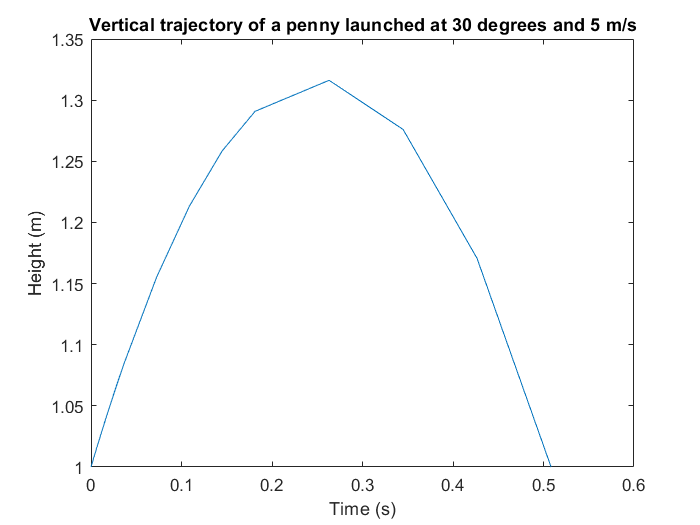

demo_speed = 5;
demo_angle = 30;
[T, M, did_hit_piano, end_time] = ode_penny(demo_speed,demo_angle);
penny_simulation_graph(T, M, did_hit_piano, end_time, demo_angle, demo_speed)

#### **Finding the corresponding speed for an angle, so that the penny hits the piano**

For every angle between 0 degrees inclusive and 90 degrees exclusive (clearly, the penny will never hit a piano that is 1 meter away if it is shot directly upwards), there will be at least corresponding speed at which the penny must be shot in order to hit the piano. Lower angles will require lower speeds, and higher angles will require higher speeds, with speeds asymptoting to infinity as the angle at which the penny is launched approaches 90 degrees.

Therefore, we created a function, `find_speed0`, that finds the corresponding speed for each angle. This function accepts an angle, and uses `fzero` to find the speed at which the `distance_error,` or the difference between the final x position of the penny and the x position of the piano, is zero. We used `fzero` rather than `fminsearch` due to the aforementioned assumption that there will be a speed for each angle where the penny will hit the piano exactly.

For example, for the angle of 30 degrees:

% find the corresponding speed for this angle
angle = 30;
initial_speed_guess = 5;
speed0 = find_speed0(angle,initial_speed_guess); % input degrees, get speed
disp("Speed at which the penny must be launched in order to hit the piano is " + speed0 + " m/s")

Speed at which the penny must be launched in order to hit the piano is 3.3745 m/s


#### **Finding which angle/speed combo hits the piano at the desired time**

Now that we can calculate the corresonding speed for each angle, we want to be able to find the angle/speed combo that will make the penny hit the piano at a given time. We have made the assumption that there will not necessarily be an angle/speed combination that gives makes the simulation `end_time` *exactly *equal to given time, but it will be close; therefore, we used `fminsearch` to find the angle combination that minimizes `time_error`, or the difference between `end_time` and the given time.

An astute reader will notice that if the force of drag were ignored, then this simulation would not require the use of ODE45, as one can use basic kinematics equations to determine the speed and angle combination for the penny to hit the piano at a given time. Therefore, we used these basic kinematics equations to determine the approximate angle needed for a given time, and passed it to the initial guess argument in `fminsearch`; the approximate speed is passed through the `time_error` function call into the initial guess argument in `fzero`, for determining an angle's corresponding speed.

Here is an example where we want the penny to hit the piano in 5 seconds:

desired_time = 5; % seconds, time we want the penny to hit the piano
x_distance = 1;
y_distance = 0;

[initial_speed_guess, angle_guess] = get_speed_and_angle(desired_time,x_distance,y_distance);
disp("The penny should be shot at approximately " + angle_guess + " degrees at " + initial_speed_guess + " m/s")

The penny should be shot at approximately 89.5323 degrees at 24.5008 m/s


The `time_error` function accepts an angle, and first calculates the corresponding speed using `find_speed0`, and then runs the ODE simulation with the angle and the corresponding speed to get `end_time`. It then returns the difference between `end_time` and `desired_time`.

error = time_error(desired_time, initial_speed_guess, angle_guess);
disp("If the penny is shot at " + angle_guess + " degrees at " + initial_speed_guess + " m/s, then the difference between end_time and desired_time is " + error)

If the penny is shot at 89.5323 degrees at 24.5008 m/s, then the difference between end_time and desired_time is 0.38433


Then, with `fminsearch`, we can use time_error to find the angle which minimizes `time_error:`

[found_angle, found_speed, error] = ode_angle_and_speed(desired_time) % seconds

found_angle = 89.4695

found_speed = 28.2035

error = 1.3033e-04

In this context, the time error is too small to be appreciable. With the angle and speed determined, let's then run the simulation to verify that it both hits the piano and achieves the desired end time.

The penny hit the piano: true
The penny took 5.0001 seconds to reach the y position of the piano.


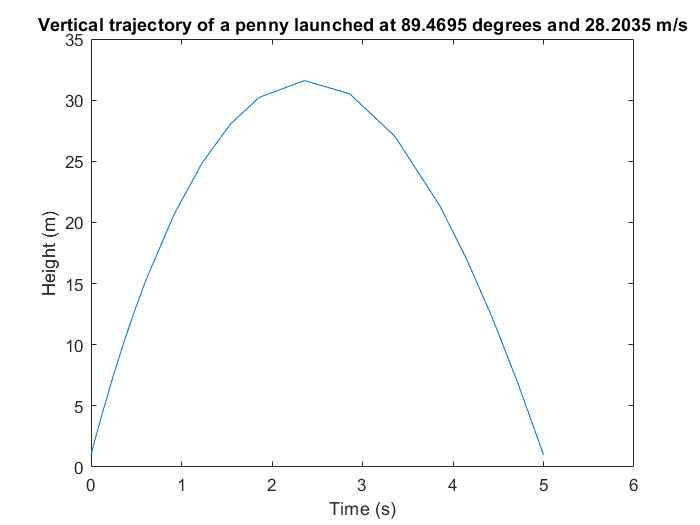

[T, M, did_hit_piano, end_time] = ode_penny(found_speed, found_angle);
penny_simulation_graph(T, M, did_hit_piano, end_time, found_angle, found_speed)

With the penny successfully hitting the piano at the given time, we can now run the simulation for each note of the song.

## Results

`notes_table` contains the time at which each penny should be thrown in order to play the song.

notes_table = readtable("hot_cross_buns.csv", "Delimiter", ",")
times = notes_table.Time

for i=1:size(times)
    desired_time = times(i);
    % get closest angle
    % get corresponding speed
    % store in matrix
end

**notes on how this works**

baseball one:

1. stop simulation when it reaches x position of green monster

2. error: calculate difference in end y height - green monster height

3. root finding: find speed at given angle where error = zero

4. fminsearch: find angle which gives the lowest speed

penny:

every angle is going to have a corresponding speed that hits the piano

1. stop simulation when it reaches y position of piano

2. distance error: calculate difference in end x position - piano x position

3. root finding: find speed at given angle where distance error is 0 (this allows us to get corresponding speed for angle)

4. time error: calculate difference in actual simulation time - desired time

5. fminsearch: find angle/speed pair which both hits the piano and minimizes the difference between simulation time and desired time

calculate approximate angle (no drag) with kinematics

give approximate angle to fminsearch

in function passed to fminsearch:

- use root finding to find speed at given angle where distance error is 0 (and give approximate speed?)

- run ODE simulation

- return time error

of the angle/speed pairs that hit the piano, which ones minimize the difference between simulation time and desired time?

## Interpretation

### **Validation**

### **Model Limitations and Future Development**

## Sources